## Resitting exam 04-07-2023

### Problem 4

Consider the domain defined by the mesh meshEscaire2foratsQuad.m (see Figure below), and made of an elastic material with Young Modulus E= `1.0e``+07`$\text{N}/\text{mm}^{2}$, Poisson ratio $\nu = 0.3$ and thickness $\text{th} = 0.20$$\text{mm}$. The two boundary internal circles are named as the figure shows $C_{1}$ and $C_{2}$

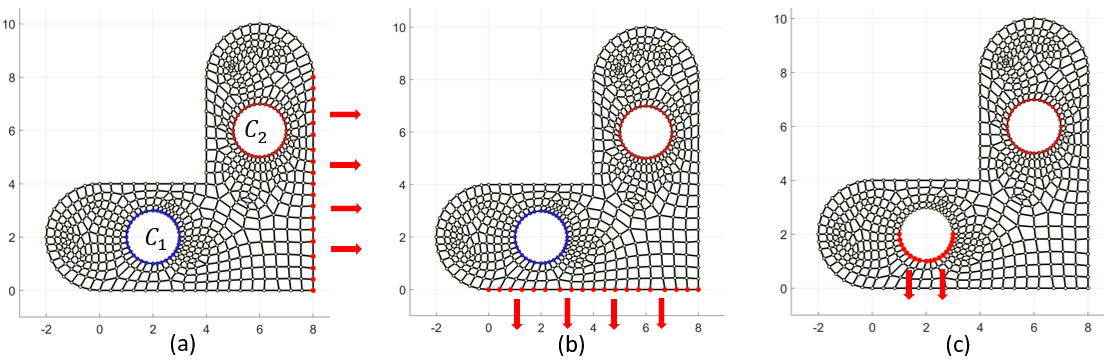	

(a) (3 points) First suppose that the piece is fixed on these two circles, while an horizontal load $\text{forceLoad} = [50000; 0]$ is applied to the right straight border as showed in the figure. Then the maximum of the absolute values of the $x$-displacements (horizontal) is:		

- 1.5608e-01

- Leave it empty (no penalty) 

- 1.5756e-01$\surd$

- 1.5887e-01

- 1.5746e-01 	

*Hint 1*. The maximum of the absolute values of the $y$-displacements (vertical) is `6.6489e-02`

**Solution.** 

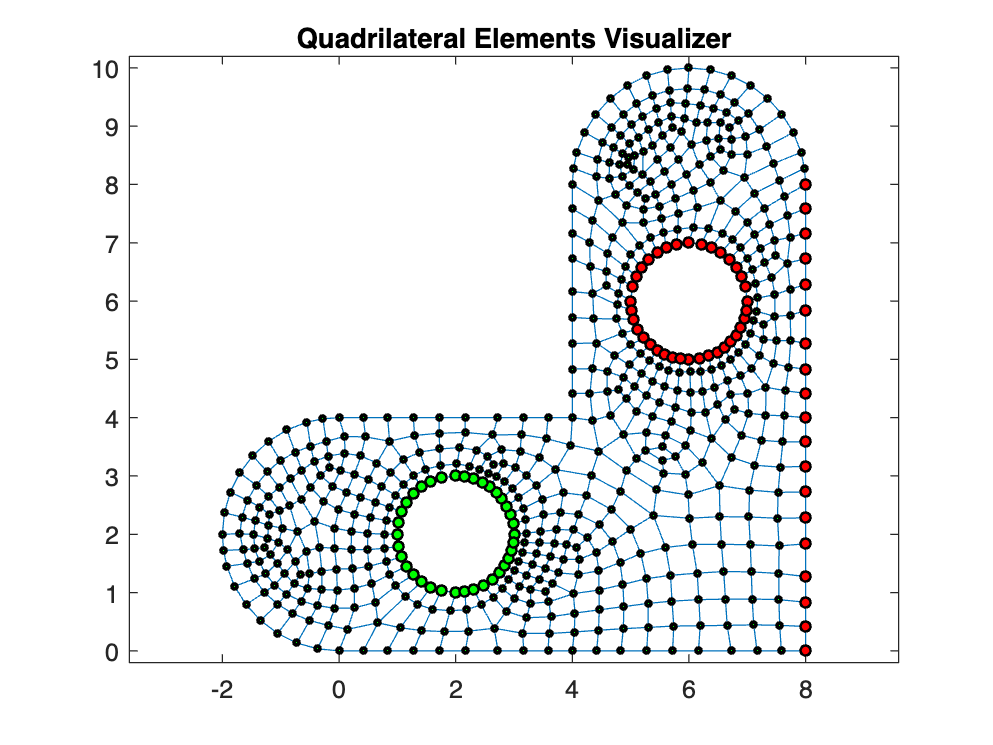

clearvars
close all

% Input parameters
%   th ................... thickness (in mm)
th=0.20;

% 
% Output parametes
%   displacments ......... numNod x 2 matrix:
%                          -- displacements(:,1) x-displacements
%                          -- displacements(:,2) y-displacements

%
% Data
%

E=1.0e+7;                  %Young Modulus (N/mm^2)
nu=0.3;                    %Poisson's ratio (adimensional)

% Define the plane elasticity problem: 
%   modelProblem=1; %plane stress
%   modelProblem=2; %plane strain

modelProblem = 1;

switch modelProblem
    case 1
        c11=E/(1-nu^2);
        c22=c11;
        c12=nu*c11;
        c21=c12;
        c33=E/(2*(1+nu));
        %fprintf('Plane stress problem\n')
    case 2
        th=1.0;
        c11=E*(1-nu)/((1+nu)*(1-2*nu));
        c22=c11;
        c12=c11*nu/(1-nu);
        c21=c12;
        c33=E/(2*(1+nu));
        fprintf('Plane strain problem\n')
    otherwise
        error('modelProblem should be 1 (stress) or 2 (strain)');
end
C=[c11, c12, 0; c21, c22, 0; 0, 0, c33];

%eval('meshEscaire2foratsQuad');
load 'meshEscaire2foratsQuad.mat'
[numNod,ndim]=size(nodes);
numElem=size(elem,1);

%
% Part (a)
%

forceLoad = [5.0e+4; 0.0e0]; %(Fx,Fy) traction force (in n/mm)

% Select Boundary points
indNodsCircC1 = find(sqrt((nodes(:,1) - 2).^2 + (nodes(:,2) - 2).^2) < 1.001);
indNodsCircC2 = find(sqrt((nodes(:,1) - 6).^2 + (nodes(:,2) - 6).^2) < 1.001);
indNodsRight=find(nodes(:,1) > 7.99 & nodes(:,2) < 8.01);

%
% Plot mesh area and boundary points
% 
numbering = 0;
plotElementsOld(nodes, elem, numbering)
hold on

plot(nodes(indNodsCircC1,1), nodes(indNodsCircC1,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor','green',...
    'markerSize', 4)
plot(nodes(indNodsCircC2,1), nodes(indNodsCircC2,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor', 'red', ...
    'markerSize', 4)
plot(nodes(indNodsRight,1), nodes(indNodsRight,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor', 'red', ...
    'markerSize', 4)
hold off

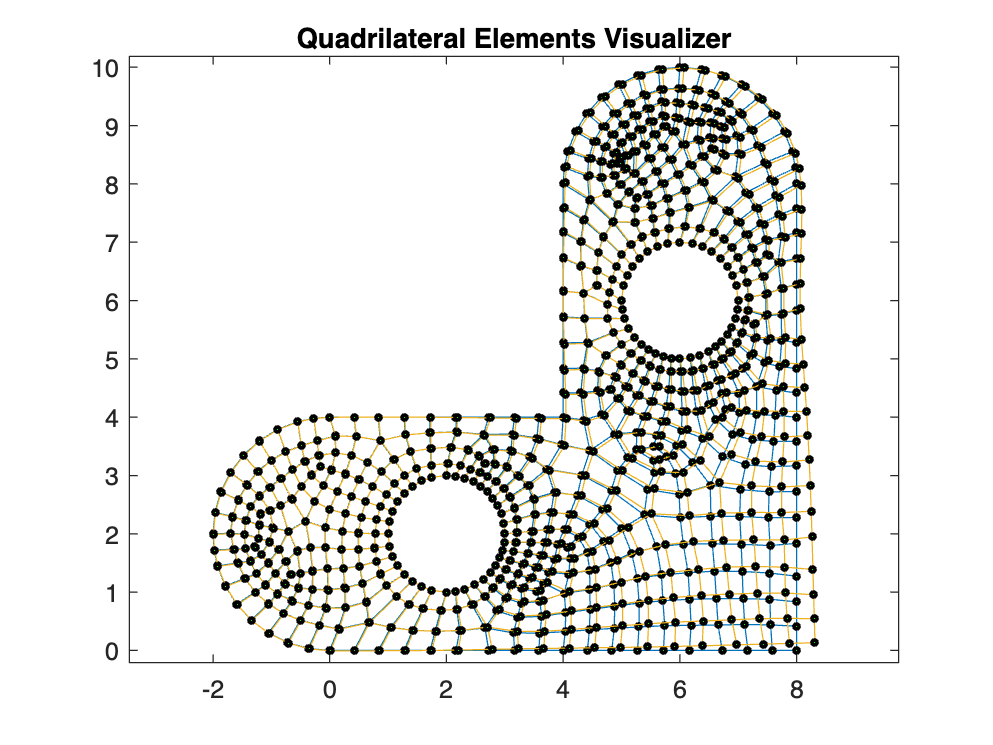


%Computation of the stiffness matrix
K=zeros(ndim*numNod);
F=zeros(ndim*numNod,1);
Q=zeros(ndim*numNod,1);

for e=1:numElem
    Ke=planeElastQuadStiffMatrix(nodes,elem,e,C,th);
    %
    % Assemble the stiffness matrices
    %
    row=[2*elem(e,1)-1; 2*elem(e,1); 2*elem(e,2)-1; 2*elem(e,2); 
         2*elem(e,3)-1; 2*elem(e,3); 2*elem(e,4)-1; 2*elem(e,4)];
    col=row;
    K(row,col)=K(row,col)+Ke;
end

%
% Boundary Conditions
%

% Natural B.C.: constant traction  on the right edge
nodLoads=indNodsRight'; %nodes the traction is applied at
Q=applyLoadsQuad(nodes,elem,nodLoads,Q,forceLoad);

% Essential B.C.: set displacements along the edges of the holes C1 and C2 to zero
fixedNodes=[
    ndim*indNodsCircC1'-1, ...
    ndim*indNodsCircC1', ...
    ndim*indNodsCircC2'-1, ...
    ndim*indNodsCircC2' ...
    ];
freeNodes=setdiff(1:ndim*numNod,fixedNodes);
u=zeros(ndim*numNod,1); %initialize the solution to u=0
u(fixedNodes)=0.0;

% Reduced system
% Remark: the linear system is not modified. This is only valid if the BC=0
Km=K(freeNodes,freeNodes);
Qm=Q(freeNodes);

%solve the reduced linar system
um=Km\Qm;
u(freeNodes)=um;

displacements=[u(1:2:end),u(2:2:end)];

% Graphical output: displacements
esc=2; %scale for the displacements
plotPlaneNodElemDespl(nodes, elem, u, esc);


fprintf(['(a) the maximum of the absolute values of the x-displacements is: %.4e\n', ...
         '    Hint 1. The maximum of the absolute values of the y-displacements is: %.4e\n'], ...
         norm(displacements(:,1), 'inf'), ...
         norm(displacements(:,2), 'inf') ...
         )

(a) the maximum of the absolute values of the x-displacements is: 1.5756e-01
    Hint 1. The maximum of the absolute values of the y-displacements is: 6.6489e-02


(b) (3 points) Maintaining fixed the two circles now suppose that only a vertical  $\text{forceLoad} = [0; -25000]$ is applied at the straight bottom border as showed in the figure. Then, the maximum of the absolute values of the $y$-displacements (vertical) of all nodes is : 

- Leave it empty (no penalty) 

- 7.9579e-02

- 7.8801e-02$\surd$

- 7.8016e-02 					

- 7.8830e-02 		

*Hint 2.* The maximum of the absolute values of the x-displacements is `3.3257e-02`

*Hint 3.* Be careful. The force loads are always column vectors 

**Solution.** 

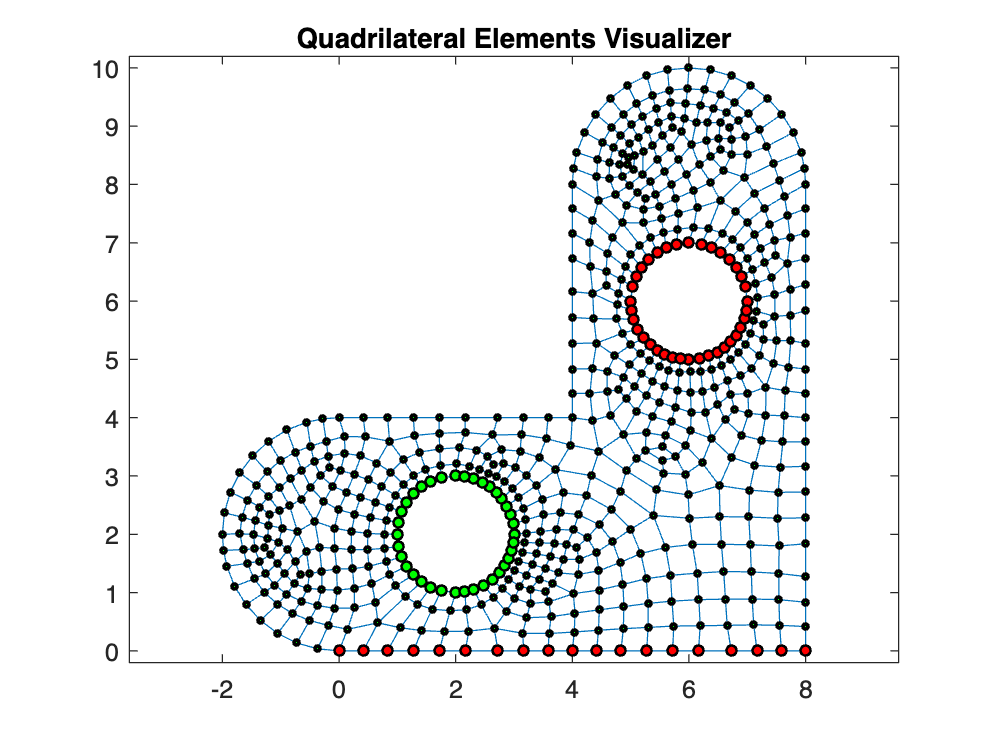

%
% Part (b)
%

forceLoad = [0.0e+00; -2.5e4]; %(Fx,Fy) traction force (in n/mm)

% Select Boundary points
indNodsCircC1 = find(sqrt((nodes(:,1) - 2).^2 + (nodes(:,2) - 2).^2) < 1.001);
indNodsCircC2 = find(sqrt((nodes(:,1) - 6).^2 + (nodes(:,2) - 6).^2) < 1.001);
indNodsBottom=find(nodes(:,1) > -0.01 & nodes(:,2) < 0.01);

%
% Plot mesh area and boundary points
%
numbering = 0;
plotElementsOld(nodes, elem, numbering);
hold on
plot(nodes(indNodsCircC1,1), nodes(indNodsCircC1,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor','green', ...
    'markerSize', 4)
plot(nodes(indNodsCircC2,1), nodes(indNodsCircC2,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor', 'red', ...
    'markerSize', 4)
plot(nodes(indNodsBottom,1), nodes(indNodsBottom,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor', 'red', ...
    'markerSize', 4)
hold off

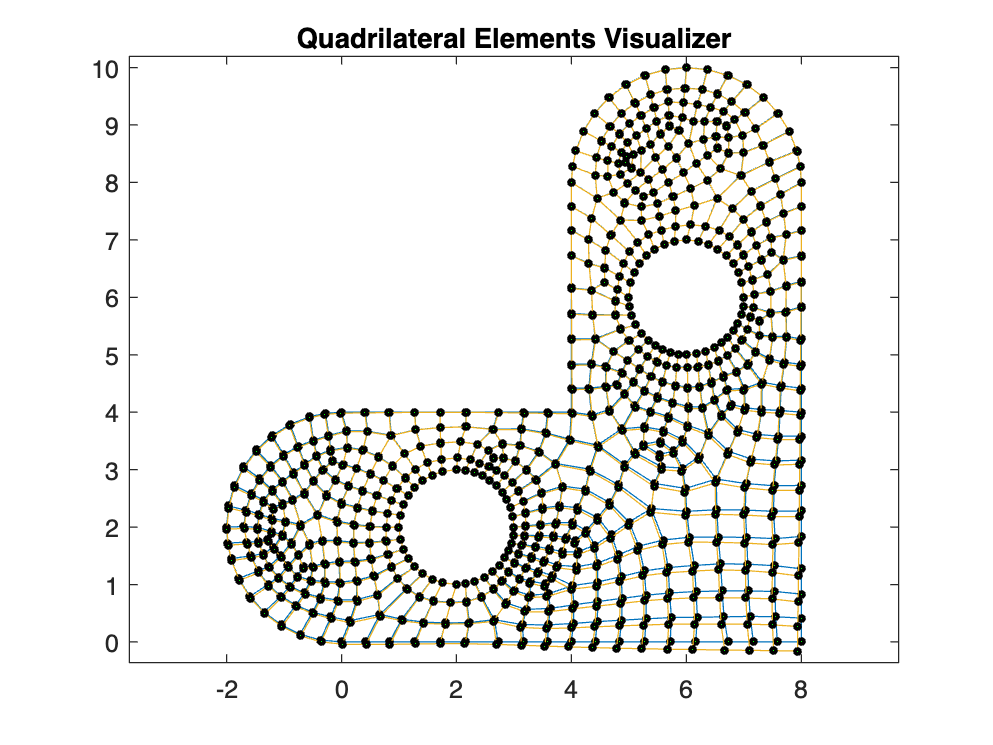


%Computation of the stiffness matrix
K=zeros(ndim*numNod);
F=zeros(ndim*numNod,1);
Q=zeros(ndim*numNod,1);
for e=1:numElem
    Ke=planeElastQuadStiffMatrix(nodes,elem,e,C,th);
    %
    % Assemble the stiffness matrices
    %
    row=[2*elem(e,1)-1; 2*elem(e,1); 2*elem(e,2)-1; 2*elem(e,2); 
         2*elem(e,3)-1; 2*elem(e,3); 2*elem(e,4)-1; 2*elem(e,4)];
    col=row;
    K(row,col)=K(row,col)+Ke;
end

%
% Boundary Conditions
%

% Natural B.C.: constant traction  on the right edge
nodLoads=indNodsBottom'; %nodes the traction is applied at
Q=applyLoadsQuad(nodes,elem,nodLoads,Q,forceLoad);

% Essential B.C.: set displacaments along the perimeter of the two holes to zero
fixedNodes=[
    ndim*indNodsCircC1'-1, ...
    ndim*indNodsCircC1', ...
    ndim*indNodsCircC2'-1, ...
    ndim*indNodsCircC2' ...
    ];
freeNodes=setdiff(1:ndim*numNod,fixedNodes);
u=zeros(ndim*numNod,1); %initialize the solution to u=0
u(fixedNodes)=0.0;

% Reduced system
% Remark: the linear system is not modified. This is only valid if the BC=0
Km=K(freeNodes,freeNodes);
Qm=Q(freeNodes);

%solve the reduced linear system
um=Km\Qm;
u(freeNodes)=um;

displacements=[u(1:2:end),u(2:2:end)];

esc=2; %scale for the displacements
plotPlaneNodElemDespl(nodes, elem, u, esc);


fprintf(['(b) the maximum of the absolute values of the y-displacements is: %.4e\n', ...
         '    Hint 2. The maximum of the absolute values of the x-displacements is: %.4e\n'], ...
         norm(displacements(:,2), 'inf'), ...
         norm(displacements(:,1), 'inf') ...
         )

(b) the maximum of the absolute values of the y-displacements is: 7.8801e-02
    Hint 2. The maximum of the absolute values of the x-displacements is: 3.3257e-02


(c) (4 points) Now suppose that only the circle $C_{2}$ is fixed, while a vertical $\text{forceLoad} = [0; -30000]$ is applied in all the nodes of the lower semicircle of $C_{1}$(including the equatorial points as the figure shows). Then, the maximum of the absolute values of the $y$-displacements (vertical) of all nodes is : 				

- 1.4896e+00

- 1.4847e+00$\surd$

- 1.4942e+00

- 1.4780e+00

- Leave it empty (no penalty) 

*Hint 4. *The maximum of the absolute values of the x-displacements is `7.3988e-01` 

**Solution.** 

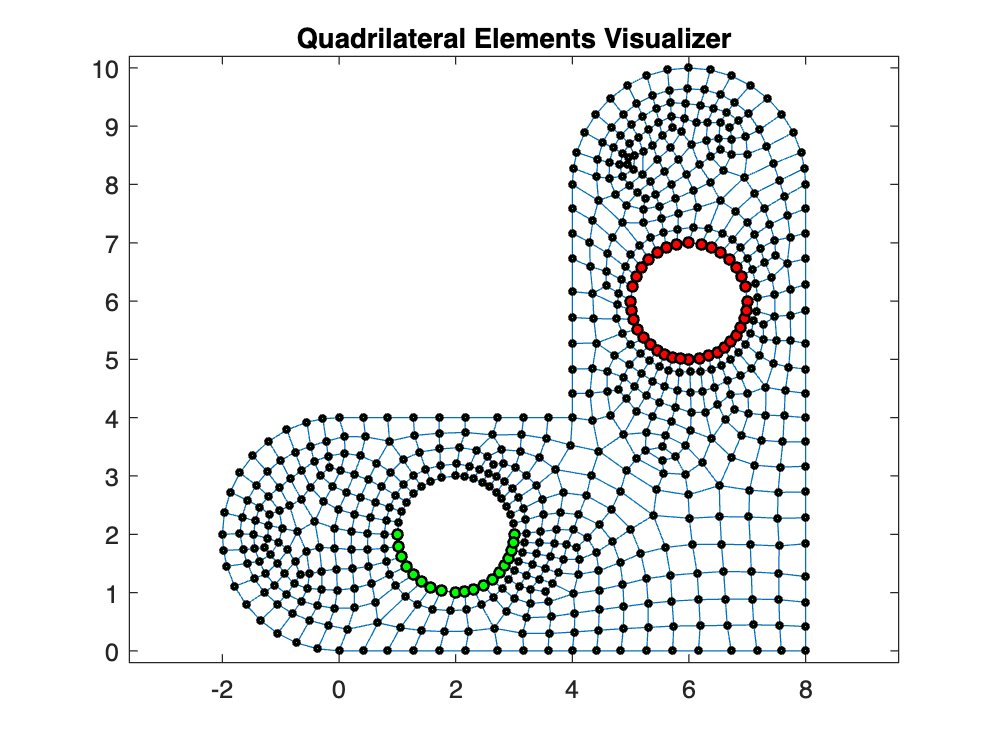

%
% Part (c)
%

forceLoad = [0.0e+4; -3.0e4]; %(Fx,Fy) traction force (in n/mm)

% Select Boundary points
indNodsCircC1Bottom = find(sqrt((nodes(:,1) - 2).^2 + (nodes(:,2) - 2).^2) < 1.001 ...
    & nodes(:,2) < 2.01);
indNodsCircC2 = find(sqrt((nodes(:,1) - 6).^2 + (nodes(:,2) - 6).^2) < 1.001);

%
% Plot mesh area and boundary points
% 
numbering=0;
plotElementsOld(nodes, elem, numbering)
hold on
plot(nodes(indNodsCircC1Bottom,1), nodes(indNodsCircC1Bottom,2), ...
    'ok', ...
    'lineWidth',1, ...
    'markerFaceColor','green', ...
    'markerSize', 4)
plot(nodes(indNodsCircC2,1), nodes(indNodsCircC2,2), ...
    'ok', ...
    'lineWidth', 1, ...
    'markerFaceColor', 'red', ...
    'markerSize', 4)
hold off

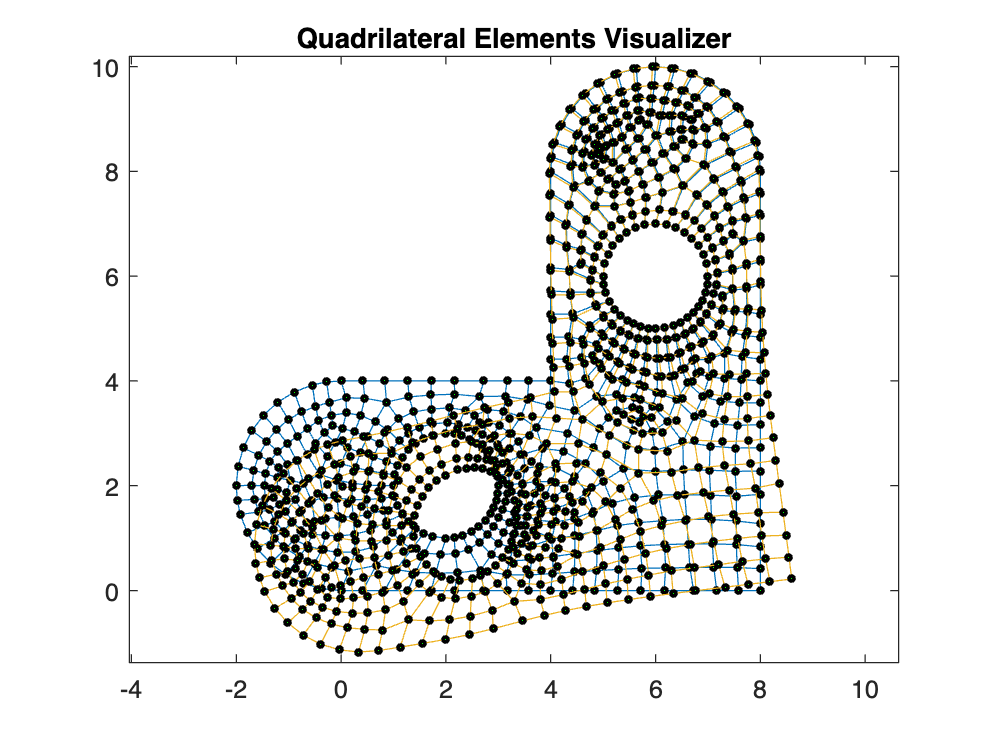


%Computation of the stiffness matrix
K=zeros(ndim*numNod);
F=zeros(ndim*numNod,1);
Q=zeros(ndim*numNod,1);
for e=1:numElem
    Ke=planeElastQuadStiffMatrix(nodes,elem,e,C,th);
    %
    % Assemble the stiffness matrices
    %
    row=[2*elem(e,1)-1; 2*elem(e,1); 2*elem(e,2)-1; 2*elem(e,2); 
         2*elem(e,3)-1; 2*elem(e,3); 2*elem(e,4)-1; 2*elem(e,4)];
    col=row;
    K(row,col)=K(row,col)+Ke;
end

%%Boundary Conditions
% Natural B.C.: constant traction  on the right edge
nodLoads=indNodsCircC1Bottom'; %nodes the traction is applied at
Q=applyLoadsQuad(nodes,elem,nodLoads,Q,forceLoad);

%% Essential B.C.: 
% set displacements along the hole to zero
fixedNodes=[
    ndim*indNodsCircC2'-1, ...
    ndim*indNodsCircC2' ...
    ];
freeNodes=setdiff(1:ndim*numNod,fixedNodes);
u=zeros(ndim*numNod,1); %initialize the solution to u=0
u(fixedNodes)=0.0;

%Reduced system
%Remark: the linear system is not modified. This is only valid if the BC=0
Km=K(freeNodes,freeNodes);
Qm=Q(freeNodes);

%solve the reduced linear system
um=Km\Qm;
u(freeNodes)=um;

displacements=[u(1:2:end),u(2:2:end)];

% Graphical output: displacements
esc=1; %scale for the displacements
plotPlaneNodElemDespl(nodes, elem, u, esc);


fprintf(['(c) the maximum of the absolute values of the y-dislacements is: %.4e\n', ...
         '    Hint 3. The maximum of the absolute values of the x-displacements is: %.4e\n'], ...
         norm(displacements(:,2), 'inf'), ...
         norm(displacements(:,1), 'inf') ...
         )

(c) the maximum of the absolute values of the y-dislacements is: 1.4847e+00
    Hint 3. The maximum of the absolute values of the x-displacements is: 7.3988e-01
